clc; clearvars;

f = 433e6; % frequency in Hertz
Re = 6371e3; % Earth radius in metres
h  = 450e3; % satellite altitude above Earth's surface in metres
elevation_angles = 5:5:90; % elevation angle range in degrees

P_t = 15; % includes HPA, Power of the transmitter in dBw
G_t = 2; % gain of the antenna, in dBi 
L_txsystem = 1; %losses due to feeding lines, connectors, filters, HPA etc in dB
L_fspl = 0; %free space path loss (calculation below) in dB
L_atm = 0; %atmospheric, rain, clouds, fog, ionosphere attenuation + (Diffusion- due to obstacles- neglect) + (Multipath fading- only for terrestrial- neglect) in dB
L_plrz = 0; %polarization mismatch, effectively 0 for circularly polarised antennas in dB
L_point = 1.5; % pointing losses, add both reciever and transmitter pointing losses in dB

G_r = 3; % gain of ground station in dBi
G_lna_ext = 0; %gain of external lna, see below for effect on F in dBi
L_rxsystem = 1.5; %losses due to feeding lines, connectors, filters, LNA, demodulators etc in dB

S_datasheet = -135; %sensitivity on datasheet (already includes the internal LNA gain effect an noise spectrum density change) in dBm
T_cold = 200; %At zenith
T_hot  = 1000; %at horizon
T_ant = 0; %Thermal temperature, Tsky(atmospheric thermal temp) + Tgnd(due to sie and back lobes) in K, Calculation below
B_datasheet = 125e3; %Bandwidth of reciever in Hz
SNRrequired_datasheet = -17.5; %required signal to noise ratio for the reciever to be able to demod the signal in dB

U_bitrate = 980e-6; %bitrate that WE pass, megabits per second
EbNo_threshold = 7.1; %minimum Eb/No required by the reciever, in dB

% Preallocate arrays
LINKMARGINP_via_sensitivity = zeros(size(elevation_angles));
LINKMARGINP_via_ebno = zeros(size(elevation_angles));
r_all = zeros(size(elevation_angles));
L_fspl_all = zeros(size(elevation_angles));
Ts_actual_all = zeros(size(elevation_angles));
CNo_all = zeros(size(elevation_angles));
EbNo_all = zeros(size(elevation_angles));

for i = 1:length(elevation_angles)
    el = elevation_angles(i); % current elevation angle
    fprintf('\n=== Elevation Angle: %.1f° ===\n', el);

    r = sqrt((Re + h)^2 - (Re * cosd(el))^2) - Re * sind(el); % Compute slant range (distance from ground station to satellite)
    EIRP = P_t + G_t - L_txsystem; %effective output power in dBm
    L_fspl = 20*log10(4*pi*r*f/299792458);
    L_prop = L_fspl + L_atm; %propogation losses

    Pr = EIRP - L_prop - L_plrz - L_point + G_r + G_lna_ext - L_rxsystem;
    C = Pr; %recieved power to digital system at reciever end, in dBm
    T_ant = T_cold + (T_hot - T_cold) * (1 - sind(el)); %using Thot an Tcold to model elevation differences
    N = S_datasheet - SNRrequired_datasheet; %noise power
    NF = N + 174 - 10*log10(B_datasheet); %noise figure at datasheet
    F = 10^(NF/10); %noise factor at datasheet

    % if external lna connected - F = Flna + (Frx - 1)/G_lna_ext;

    Tr = (F-1)*290; %Thermal temp at reciever end
    Ts_actual = T_ant + Tr; %Thermal temp of system incluing Tatm and Tr (entire system)
    Ts_spec = F*290; %Thermal temp use by mnufacturer to calculate
    correction = 10*log10(Ts_actual/Ts_spec); %change due to Tatm

    S_actual = S_datasheet + correction; %actual sensitivity of reciever system
    Psensitivity = S_actual;
    LINKMARGINP_via_sensitivity(i) = Pr - Psensitivity;

    No = 1.380649e-23 * Ts_actual; %Noise spectral density in W/Hz
    No = 10*log10(No); %nsd in dBW/Hz

    C_ = C - 30; %C in dBW
    CNo = C_ - No; %received carrier power/noise spectral density in dB-Hz
    EbNo_calculated = CNo - 10*log10(U_bitrate) - 60; %received EbNo in dB, 60 subtracte to convert from Mbps to bps
    LINKMARGINP_via_ebno(i) = EbNo_calculated - EbNo_threshold;

    % Store results for table
    r_all(i) = r;
    L_fspl_all(i) = L_fspl;
    Ts_actual_all(i) = Ts_actual;
    CNo_all(i) = CNo;
    EbNo_all(i) = EbNo_calculated;

    % Print key values for this elevation
    fprintf('Slant range (r): %.2f km\n', r/1e3);
    fprintf('Free-space path loss (L_fspl): %.2f dB\n', L_fspl);
    fprintf('System temperature (Ts_actual): %.2f K\n', Ts_actual);
    fprintf('C/N0: %.2f dB-Hz\n', CNo);
    fprintf('Eb/No: %.2f dB\n', EbNo_calculated);
    fprintf('Link Margin (via Eb/No): %.2f dB\n', LINKMARGINP_via_ebno(i));
    fprintf('------------------------------------------\n');
end


=== Elevation Angle: 5.0° ===


Slant range (r): 1943.68 km


Free-space path loss (L_fspl): 150.95 dB


System temperature (Ts_actual): 1676.58 K


C/N0: 31.40 dB-Hz


Eb/No: 1.49 dB


Link Margin (via Eb/No): -5.61 dB


------------------------------------------



=== Elevation Angle: 10.0° ===


Slant range (r): 1569.57 km


Free-space path loss (L_fspl): 149.09 dB


System temperature (Ts_actual): 1607.39 K


C/N0: 33.44 dB-Hz


Eb/No: 3.53 dB


Link Margin (via Eb/No): -3.57 dB


------------------------------------------



=== Elevation Angle: 15.0° ===


Slant range (r): 1293.07 km


Free-space path loss (L_fspl): 147.41 dB


System temperature (Ts_actual): 1539.25 K


C/N0: 35.32 dB-Hz


Eb/No: 5.40 dB


Link Margin (via Eb/No): -1.70 dB


------------------------------------------



=== Elevation Angle: 20.0° ===


Slant range (r): 1089.70 km


Free-space path loss (L_fspl): 145.92 dB


System temperature (Ts_actual): 1472.69 K


C/N0: 36.99 dB-Hz


Eb/No: 7.08 dB


Link Margin (via Eb/No): -0.02 dB


------------------------------------------



=== Elevation Angle: 25.0° ===


Slant range (r): 938.75 km


Free-space path loss (L_fspl): 144.63 dB


System temperature (Ts_actual): 1408.21 K


C/N0: 38.48 dB-Hz


Eb/No: 8.57 dB


Link Margin (via Eb/No): 1.47 dB


------------------------------------------



=== Elevation Angle: 30.0° ===


Slant range (r): 824.96 km


Free-space path loss (L_fspl): 143.51 dB


System temperature (Ts_actual): 1346.31 K


C/N0: 39.80 dB-Hz


Eb/No: 9.89 dB


Link Margin (via Eb/No): 2.79 dB


------------------------------------------



=== Elevation Angle: 35.0° ===


Slant range (r): 737.78 km


Free-space path loss (L_fspl): 142.54 dB


System temperature (Ts_actual): 1287.44 K


C/N0: 40.97 dB-Hz


Eb/No: 11.05 dB


Link Margin (via Eb/No): 3.95 dB


------------------------------------------



=== Elevation Angle: 40.0° ===


Slant range (r): 669.99 km


Free-space path loss (L_fspl): 141.70 dB


System temperature (Ts_actual): 1232.08 K


C/N0: 41.99 dB-Hz


Eb/No: 12.08 dB


Link Margin (via Eb/No): 4.98 dB


------------------------------------------



=== Elevation Angle: 45.0° ===


Slant range (r): 616.67 km


Free-space path loss (L_fspl): 140.98 dB


System temperature (Ts_actual): 1180.62 K


C/N0: 42.90 dB-Hz


Eb/No: 12.99 dB


Link Margin (via Eb/No): 5.89 dB


------------------------------------------



=== Elevation Angle: 50.0° ===


Slant range (r): 574.38 km


Free-space path loss (L_fspl): 140.36 dB


System temperature (Ts_actual): 1133.47 K


C/N0: 43.69 dB-Hz


Eb/No: 13.78 dB


Link Margin (via Eb/No): 6.68 dB


------------------------------------------



=== Elevation Angle: 55.0° ===


Slant range (r): 540.74 km


Free-space path loss (L_fspl): 139.84 dB


System temperature (Ts_actual): 1090.98 K


C/N0: 44.38 dB-Hz


Eb/No: 14.47 dB


Link Margin (via Eb/No): 7.37 dB


------------------------------------------



=== Elevation Angle: 60.0° ===


Slant range (r): 514.02 km


Free-space path loss (L_fspl): 139.40 dB


System temperature (Ts_actual): 1053.49 K


C/N0: 44.98 dB-Hz


Eb/No: 15.06 dB


Link Margin (via Eb/No): 7.96 dB


------------------------------------------



=== Elevation Angle: 65.0° ===


Slant range (r): 493.01 km


Free-space path loss (L_fspl): 139.03 dB


System temperature (Ts_actual): 1021.26 K


C/N0: 45.47 dB-Hz


Eb/No: 15.56 dB


Link Margin (via Eb/No): 8.46 dB


------------------------------------------



=== Elevation Angle: 70.0° ===


Slant range (r): 476.81 km


Free-space path loss (L_fspl): 138.74 dB


System temperature (Ts_actual): 994.55 K


C/N0: 45.88 dB-Hz


Eb/No: 15.97 dB


Link Margin (via Eb/No): 8.87 dB


------------------------------------------



=== Elevation Angle: 75.0° ===


Slant range (r): 464.78 km


Free-space path loss (L_fspl): 138.52 dB


System temperature (Ts_actual): 973.57 K


C/N0: 46.19 dB-Hz


Eb/No: 16.28 dB


Link Margin (via Eb/No): 9.18 dB


------------------------------------------



=== Elevation Angle: 80.0° ===


Slant range (r): 456.47 km


Free-space path loss (L_fspl): 138.37 dB


System temperature (Ts_actual): 958.46 K


C/N0: 46.42 dB-Hz


Eb/No: 16.51 dB


Link Margin (via Eb/No): 9.41 dB


------------------------------------------



=== Elevation Angle: 85.0° ===


Slant range (r): 451.60 km


Free-space path loss (L_fspl): 138.27 dB


System temperature (Ts_actual): 949.35 K


C/N0: 46.55 dB-Hz


Eb/No: 16.64 dB


Link Margin (via Eb/No): 9.54 dB


------------------------------------------



=== Elevation Angle: 90.0° ===


Slant range (r): 450.00 km


Free-space path loss (L_fspl): 138.24 dB


System temperature (Ts_actual): 946.31 K


C/N0: 46.60 dB-Hz


Eb/No: 16.68 dB


Link Margin (via Eb/No): 9.58 dB


------------------------------------------


% Produce table of results
Results = table(elevation_angles.', r_all.'/1e3, L_fspl_all.', Ts_actual_all.', ...
    CNo_all.', EbNo_all.', LINKMARGINP_via_sensitivity.', LINKMARGINP_via_ebno.', ...
    'VariableNames', {'Elevation_deg', 'SlantRange_km', 'L_fspl_dB', 'Ts_K', ...
    'CNo_dBHz', 'EbNo_dB', 'LinkMargin_Sens_dB', 'LinkMargin_EbNo_dB'});

disp(Results);

    Elevation_deg    SlantRange_km    L_fspl_dB     Ts_K     CNo_dBHz    EbNo_dB    LinkMargin_Sens_dB    LinkMargin_EbNo_dB
    _____________    _____________    _________    ______    ________    _______    __________________    __________________

          5             1943.7         150.95      1676.6     31.405     1.4926            -2.0394              -5.6074     
         10             1569.6         149.09      1607.4     33.445     3.5326         0.00053995              -3.5674     
         15             1293.1         147.41      1539.3     35.316     5.4038             1.8718              -1.6962     
         20             1089.7         145.92      1472.7     36.994     7.0821             3.5501    

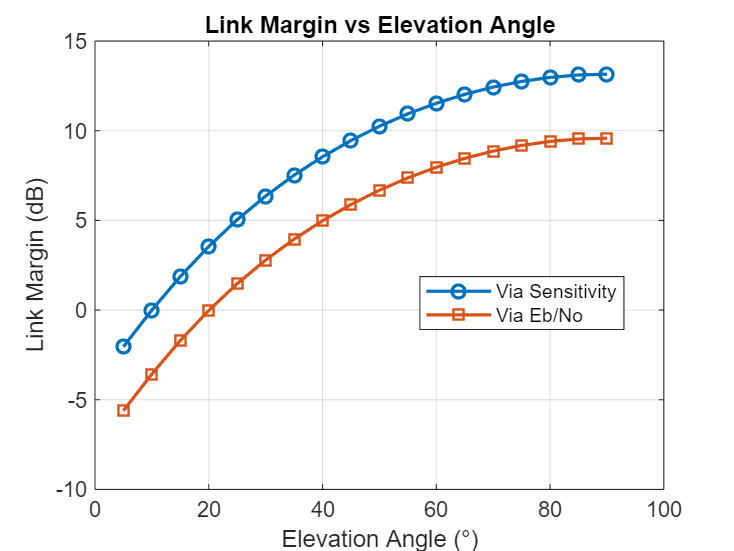

% Plot link margins vs elevation angle
figure;
plot(elevation_angles, LINKMARGINP_via_sensitivity, '-o', 'LineWidth', 1.5); hold on;
plot(elevation_angles, LINKMARGINP_via_ebno, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Elevation Angle (°)');
ylabel('Link Margin (dB)');
title('Link Margin vs Elevation Angle');
legend('Via Sensitivity', 'Via Eb/No', 'Location', 'best');